# **Gruppo G**

## **Studenti:**

**Fares Peter William Guirguis - mat.721654**

**Mirandola Edoardo - mat. 723993**

**Pennacchio Manuele -mat. 721965**

# Identificazione:

I sistemi meccanici hanno dei limiti di  posizione e di velocita per cui bisogna mettere dei limiti massimi e minimi all'ingresso cosi possiamo evitare (danni nei sistemi reali schiaccio delle fine corse) o problemi saturazioni nei sitemi digitali 

Purtroppo gli attrittto statci causano delle imprecizioni nella identificazione , per cui vengono appliate all'ingresso due segnali 

- segnale di eccitazione (segnale ad alta frequenza che varia nel tempo) 

- segnale portante  (bassa frequenza)

**La portante:**

La portante è un segnale che varia gradualmente sia nella parte positiva che in quella negativa, al fine di evitare sbalzi bruschi all'estremità.

**il segnale eccitante:**

un segnale a  frequenza variabile 

%inzializzazione del programma 
clc;
clear all;
close all;
Group_name = 'GruppoG';
%addpath('C:\Users\edoar\Documenti\git hub\Progetto_LAB_Automatica') % aggiungi cartella path]) %aggiunge al path la cartella modelli (che deve essere nella cartella superiore)
%creare l'istnza del sistema
model=ElasticRoboticSystem();
model.show;

This system has 4 outputs:
- position_1
- position_2
- velocity_1
- velocity_2
This system has 2 inputs:
- torque_1, with maximum limit = 600.000000
- torque_2, with maximum limit = 600.000000


%numero output
output_number=model.getOutputNumber 

output_number = 4

%visualizzazione dei output del sistema
for i=1:output_number
    fprintf('Output %d:    %s\n',i,model.getOutputName{i});
end

Output 1:    position_1
Output 2:    position_2
Output 3:    velocity_1
Output 4:    velocity_2


%sampling time 
st=model.getSamplingPeriod;
%inzializzazione del controllore
cs=ControlledSystemScara(model,Group_name);

%impostazione dei parametri del pi arbitrariamente in modo che non sia
%instabile 
%g1
Kp_g1 = 0.1;
Ki_g1 = 0.1;
%g2
Kp_g2 = 0.01;
Ki_g2 = 0.1;
ctrl = ScaraBasicPIController(st, Kp_g1, Ki_g1, Kp_g2, Ki_g2);
%impostazione della coppia massima
ctrl.setUMax(model.getUMax);
%impostazione della isatnza del controllore
cs.setController(ctrl);
%impostazione dei parametri di input
omega_portante = 1; %rad/s
ampiezza_portante=250;
T_portante=2*pi/omega_portante;

la durata del segnale dovrebbe essere al meno un periodo  

t=(0:st:(1.1*T_portante))'; %time descritazation
portante=ampiezza_portante*sin(omega_portante*t); %sine wave K=A*sen(W*t+phi) or can be also cosine wave
w0=omega_portante*10; %rad/s 
w1=pi/st; %rad/s
%creating a chirp signal
control_action_identificazione = chirp(t,w0/2/pi,t(end),w1/2/pi, 'logarithmic'); %chirp logaritmico
ampliezza_identificazione=250;

sommo la chirp con la portante

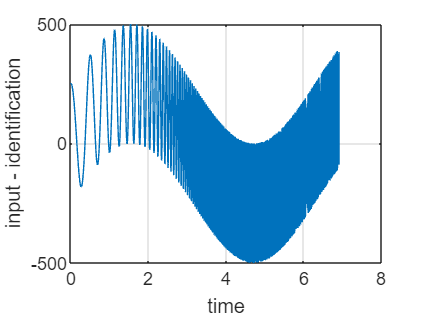

control_action=portante+ control_action_identificazione*ampliezza_identificazione; 
figure
plot(t,control_action)
xlabel('time')
ylabel('input - identification')
grid on

Spettrogramma (contenuto frequenziale al variare del tempo)

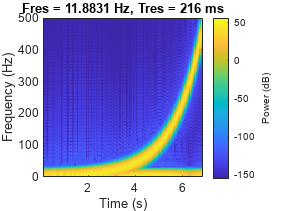

pspectrum(control_action,1/st,'spectrogram'); 

stimulo il sistema con il segnale creato sul giunto 1

reference = zeros(length(t),model.getOutputNumber);%intializing an array 
exciting_signal_g1 = zeros(length(t),model.getInputNumber);%intializing an array 
exciting_signal_g1(:,1) = control_action;
cs.initialize % intialization
%applaying the input signal to eccite the system G1
for idx=1:length(t)
    [process_output_g1(idx,:),control_action_g1(idx,:),t_g1(idx,1)]=cs.step(reference(idx,:)',exciting_signal_g1(idx,:)');  
end

stimulo il sistema con il segnale creato sul giunto 2

exciting_signal_g2 = zeros(length(t),model.getInputNumber);%intializing an array 
exciting_signal_g2(:,2) = control_action;%intializing an array 
cs.initialize % intialization
%applaying the input signal to eccite the system G2
for idx=1:length(t)
    [process_output_g2(idx,:),control_action_g2(idx,:),t_g2(idx,1)]=cs.step(reference(idx,:)',exciting_signal_g2(idx,:)');  
end

## **Risultati giunto 1**

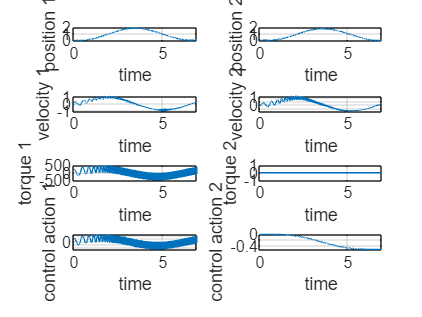

figure
subplot(4,2,1)
plot(t_g1,process_output_g1(:,1))
xlabel('time')
ylabel('position 1')
grid on

subplot(4,2,3)
plot(t_g1,process_output_g1(:,3))
xlabel('time')
ylabel('velocity 1')
grid on

subplot(4,2,5)
plot(t_g1,exciting_signal_g1(:,1))
xlabel('time')
ylabel('torque 1')
grid on

subplot(4,2,7)
plot(t_g1,control_action_g1(:,1))
xlabel('time')
ylabel('control action 1')
grid on

subplot(4,2,2)
plot(t_g1,process_output_g1(:,2))
xlabel('time')
ylabel('position 2')
grid on

subplot(4,2,4)
plot(t_g1,process_output_g1(:,4))
xlabel('time')
ylabel('velocity 2')
grid on

subplot(4,2,6)
plot(t_g1,exciting_signal_g1(:,2))
xlabel('time')
ylabel('torque 2')
grid on

subplot(4,2,8)
plot(t_g1,control_action_g1(:,2))
xlabel('time')
ylabel('control action 2')
grid on

### Risultati giunto 2

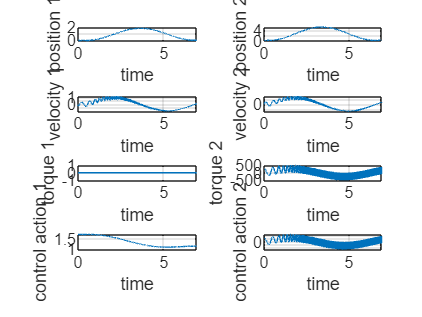

figure
subplot(4,2,1)
plot(t_g2,process_output_g2(:,1))
xlabel('time')
ylabel('position 1')
grid on

subplot(4,2,3)
plot(t_g2,process_output_g2(:,3))
xlabel('time')
ylabel('velocity 1')
grid on

subplot(4,2,5)
plot(t_g2,exciting_signal_g2(:,1))
xlabel('time')
ylabel('torque 1')
grid on

subplot(4,2,7)
plot(t_g2,control_action_g2(:,1))
xlabel('time')
ylabel('control action 1')
grid on

subplot(4,2,2)
plot(t_g2,process_output_g2(:,2))
xlabel('time')
ylabel('position 2')
grid on

subplot(4,2,4)
plot(t_g2,process_output_g2(:,4))
xlabel('time')
ylabel('velocity 2')
grid on

subplot(4,2,6)
plot(t_g2,exciting_signal_g2(:,2))
xlabel('time')
ylabel('torque 2')
grid on

subplot(4,2,8)
plot(t_g2,control_action_g2(:,2))
xlabel('time')
ylabel('control action 2')
grid on

### Risposta in frequenza

#### Giunto 1

%identification G1
identification_g1 = iddata(process_output_g1(:,3),control_action_g1(:,1),st);
frequency_response_identification_g1 = spafdr(identification_g1);

#### Giunto 2

%identification G2
identification_g2 = iddata(process_output_g2(:,4),control_action_g2(:,2),st);
frequency_response_identification_g2 = spafdr(identification_g2);

#### Bode diagram

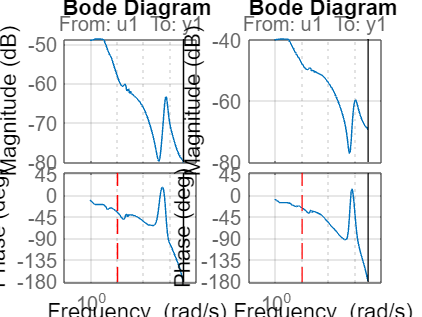

figure
subplot(1,2,1)
bode(frequency_response_identification_g1)
hold on
plot(w0*[1 1],ylim,'--r') 
hold off
grid on

subplot(1,2,2)
bode(frequency_response_identification_g2)
hold on
plot(w0*[1 1],ylim,'--r') 
hold off
grid on

## Stima dei modelli

### Giunto 1

rendere delle frequenze piu' importanti rispetto alri xk le alte frequenze vengono tagliati dal filtro le basse frequenze vengono compensati dal controllore 

lo spetro tra 100 hz e 1000 hz

peso = ones(length(frequency_response_identification_g1.Frequency),1);

weight1_1 = 100;
weight1_2 = 1000;

peso(frequency_response_identification_g1.Frequency<weight1_1) = 1e-3;
peso(frequency_response_identification_g1.Frequency>weight1_2) = 1e-3;   

stimo i modelli

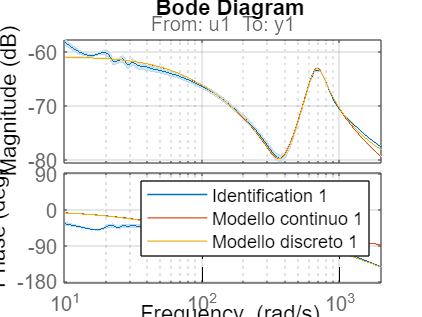

opts = ssestOptions('WeightingFilter', peso, 'EnforceStability', 1);
modello_continuo_g1 = ssest(frequency_response_identification_g1, 3, opts);
modello_discreto_g1 = ssest(frequency_response_identification_g1, 3, 'Ts', st, opts);
figure
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on'; %per avere un range tra 0 e 2 pi

h = bodeplot(frequency_response_identification_g1, bode_opts);
hold on
showConfidence(h,3)
bode(modello_continuo_g1,modello_discreto_g1, bode_opts)

%plot le linee delle frequenze che mi intressano
plot([weight1_1 weight1_1],ylim,'--k')
plot([weight1_2 weight1_2],ylim,'--k')

grid on
xlim([10 2e3])  %range di frequenze

legend('Identification 1','Modello continuo 1','Modello discreto 1')

### Giunto 2

rendere delle frequenze piu' importanti rispetto alri xk le alte frequenze vengono tagliati dal filtro le basse frequenze vengono compensati dal controllore 

lo spetro tra 250 hz e 1000 hz

peso = ones(length(frequency_response_identification_g2.Frequency),1);

weight2_1 = 250;
weight2_2 = 1000;

peso(frequency_response_identification_g2.Frequency<weight2_1) = 1e-3;
peso(frequency_response_identification_g2.Frequency>weight2_2) = 1e-3;   

stimo il modello

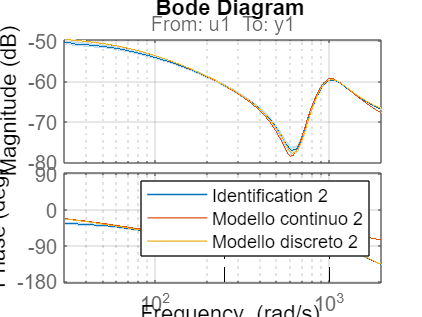

opts=ssestOptions('WeightingFilter',peso,'EnforceStability',1);
modello_continuo_g2 = ssest(frequency_response_identification_g2,5,opts);
modello_discreto_g2 = ssest(frequency_response_identification_g2,5,'Ts',st,opts);
figure
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on'; %per avere un range tra 0 e 2 pi

h=bodeplot(frequency_response_identification_g2, bode_opts);
hold on
showConfidence(h,3)
bode(modello_continuo_g2,modello_discreto_g2, bode_opts)

%plot le linee delle frequenze che mi intressano
plot([weight2_1 weight2_1],ylim,'--k')
plot([weight2_2 weight2_2],ylim,'--k')


hold off
grid on
xlim([30 2e3]) % range di frequenze

legend('Identification 2','Modello continuo 2','Modello discreto 2')

## Definizione segnale di validazione

Per la fase di validazione, è stato scelto un segnale composto da una chirp e una portante, utilizzando parametri diversi rispetto al caso precedente. La frequenza della chirp è impostata a 2 rad/s, mentre l'ampiezza della portante è di 130 Nm.

- Il segnale di chirp è un segnale che varia linearmente o logaritmicamente la sua frequenza nel tempo, partendo da una frequenza iniziale e raggiungendo una frequenza finale. Questa variazione graduale di frequenza può essere utile per testare la risposta del sistema in diverse condizioni dinamiche.

- La portante, con un'ampiezza di 130 Nm, viene sommata al segnale di chirp. Questo contributo aggiuntivo permette di mantenere una velocità diversa da zero per lunghi tratti, considerando l'effetto dell'attrito statico. L'ampiezza della portante è stata tarata in modo da limitare i cambi di direzione bruschi e ottenere una variazione più graduale della velocità.

- Combinando la chirp e la portante nel segnale composto, è possibile stimolare il sistema e verificare la sua risposta in condizioni reali. È importante considerare i limiti di posizione e velocità massima del sistema durante la somma dei segnali e monitorare l'ingresso per evitare saturazioni e garantire un funzionamento sicuro.

- In sintesi, per la fase di validazione è stato scelto un segnale composto da una chirp e una portante. La chirp fornisce una variazione graduale della frequenza nel tempo, mentre la portante contribuisce a mantenere una velocità diversa da zero, considerando i limiti di posizione e velocità massima.

per la simulazione abbiamo seguito la stessa strategia del segnale di ingresso della validazione 

possiamo mettere al posto del seno coseno

omega_portante_validation=2;
ampiezza_portante_validation=130;
T_portante_val=2*pi/omega_portante_validation;

t_val=(0:st:(1.1*T_portante_val))';
portante_v=ampiezza_portante_validation*sin(omega_portante_validation*t_val);

w0_v=omega_portante_validation*10; %rad/s
w1_v=pi/st; %rad/s

control_action_validazione = chirp(t_val,w0_v/2/pi,t_val(end),w1_v/2/pi, 'quadratic');
ampliezza_validazione=300;

control_action_validation = portante_v + control_action_validazione*ampliezza_validazione;

Plot lo spetro del segnale di ingresso 

figure
title("Identificazione")
pspectrum(control_action,1/st,'spectrogram');

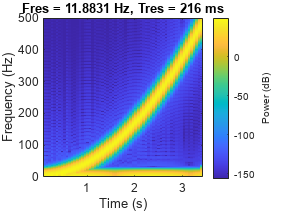

figure
title("Validazione")
pspectrum(control_action_validation,1/st,'spectrogram');

####  Joint 1 signal vaidation

input=Exciting_signal +chirp            G**iunto 1** 

exciting_signal_g1_validation = zeros(length(t_val),model.getInputNumber);
exciting_signal_g1_validation(:,1) = control_action_validation;

applico il segnale sul modello stimato

cs.initialize 
for idx=1:length(t_val)
    [process_output_g1_validation(idx,:),control_action_g1_validation(idx,:),t_g1_validation(idx,1)]=cs.step(reference(idx,:)',exciting_signal_g1_validation(idx,:)');  
end


#### Simulazione Giunto 2 Segnale Validazione

input=Exciting_signal +chirp            G**iunto 2**

exciting_signal_q2_validation = zeros(length(t_val),model.getInputNumber);
exciting_signal_q2_validation(:,2) = control_action_validation;

applico il segnale sul modello stimato

cs.initialize 
for idx=1:length(t_val)
    [process_output_g2_validation(idx,:),control_action_g2_validation(idx,:),t_g2_validation(idx,1)]=cs.step(reference(idx,:)',exciting_signal_q2_validation(idx,:)');  
end

#### Risposta in frequenza Validazione

#### Giunto 1

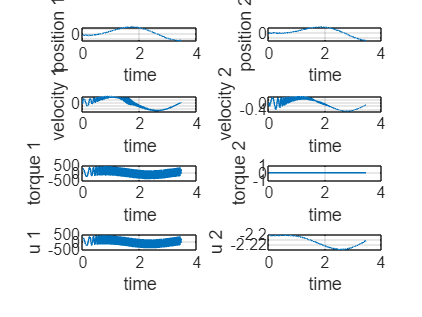

validation_g1 = iddata(process_output_g1_validation(:,3),control_action_g1_validation(:,1),st);
frequency_response_validazione_g1 = spafdr(validation_g1);
figure
subplot(4,2,1)
plot(t_g1_validation,process_output_g1_validation(:,1))
xlabel('time')
ylabel('position 1')
grid on

subplot(4,2,3)
plot(t_g1_validation,process_output_g1_validation(:,3))
xlabel('time')
ylabel('velocity 1')
grid on

subplot(4,2,5)
plot(t_g1_validation,exciting_signal_g1_validation(:,1))
xlabel('time')
ylabel('torque 1')
grid on

subplot(4,2,7)
plot(t_g1_validation,control_action_g1_validation(:,1))
xlabel('time')
ylabel('u 1')
grid on

subplot(4,2,2)
plot(t_g1_validation,process_output_g1_validation(:,2))
xlabel('time')
ylabel('position 2')
grid on

subplot(4,2,4)
plot(t_g1_validation,process_output_g1_validation(:,4))
xlabel('time')
ylabel('velocity 2')
grid on

subplot(4,2,6)
plot(t_g1_validation,exciting_signal_g1_validation(:,2))
xlabel('time')
ylabel('torque 2')
grid on

subplot(4,2,8)
plot(t_g1_validation,control_action_g1_validation(:,2))
xlabel('time')
ylabel('u 2')
grid on

#### Risposta in frequenza Validazione

#### Giunto 2

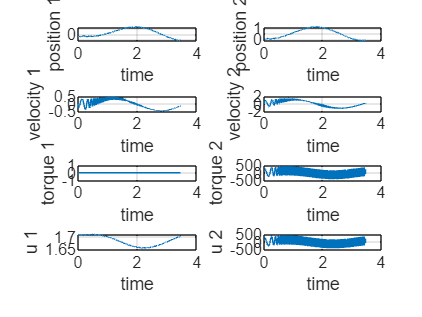

validation_g2 = iddata(process_output_g2_validation(:,4),control_action_g2_validation(:,2),st);
frequency_response_validazione_g2 = spafdr(validation_g2);
figure
subplot(4,2,1)
plot(t_g2_validation,process_output_g2_validation(:,1))
xlabel('time')
ylabel('position 1')
grid on

subplot(4,2,3)
plot(t_g2_validation,process_output_g2_validation(:,3))
xlabel('time')
ylabel('velocity 1')
grid on

subplot(4,2,5)
plot(t_g2_validation,exciting_signal_q2_validation(:,1))
xlabel('time')
ylabel('torque 1')
grid on

subplot(4,2,7)
plot(t_g2_validation,control_action_g2_validation(:,1))
xlabel('time')
ylabel('u 1')
grid on

subplot(4,2,2)
plot(t_g2_validation,process_output_g2_validation(:,2))
xlabel('time')
ylabel('position 2')
grid on

subplot(4,2,4)
plot(t_g2_validation,process_output_g2_validation(:,4))
xlabel('time')
ylabel('velocity 2')
grid on

subplot(4,2,6)
plot(t_g2_validation,exciting_signal_q2_validation(:,2))
xlabel('time')
ylabel('torque 2')
grid on

subplot(4,2,8)
plot(t_g2_validation,control_action_g2_validation(:,2))
xlabel('time')
ylabel('u 2')
grid on

#### Diagramma di bode della risposta in frequenza

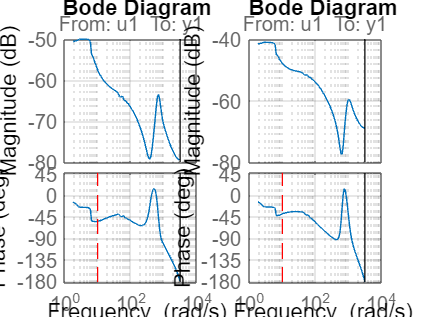

figure
subplot(1,2,1)
bode(frequency_response_validazione_g1)
hold on
plot(w0*[1 1],ylim,'--r') % frequenza iniziale del chirp
hold off
grid on

subplot(1,2,2)
bode(frequency_response_validazione_g2)
hold on
plot(w0*[1 1],ylim,'--r') % frequenza iniziale del chirp
hold off
grid on

## Confronto validazione e identificazione close loop

#### Giunto 1

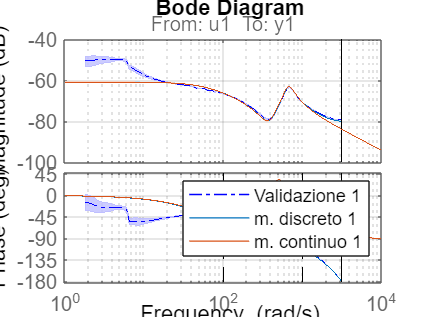

figure
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
h=bodeplot(frequency_response_validazione_g1,'-.', bode_opts);
showConfidence(h,3)
hold on
bode(modello_discreto_g1, bode_opts)
bode(modello_continuo_g1, bode_opts)
plot([weight1_1 weight1_1],ylim,'--k')
plot([weight1_2 weight1_2],ylim,'--k')
grid on

legend('Validazione 1','m. discreto 1','m. continuo 1')

Risposta in frequenza della validazione e identificazione

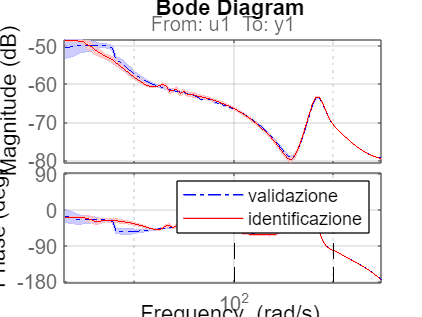

figure
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
h=bodeplot(frequency_response_validazione_g1,'b-.', bode_opts);
showConfidence(h,3)
hold on
bode(frequency_response_identification_g1, bode_opts,'r')
plot([weight1_1 weight1_1],ylim,'--k')
plot([weight1_2 weight1_2],ylim,'--k')
grid on

legend('validazione','identificazione')
xlim([2 3e3])

#### Giunto 2

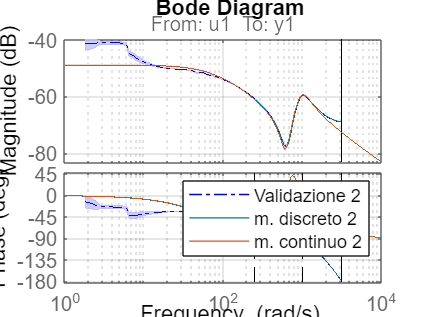

figure
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
h=bodeplot(frequency_response_validazione_g2,'-.', bode_opts);
showConfidence(h,3)
hold on
bode(modello_discreto_g2, bode_opts)
hold on
bode(modello_continuo_g2, bode_opts)
hold on 
plot([weight2_1 weight2_1],ylim,'--k')
hold on
plot([weight2_2 weight2_2],ylim,'--k')
grid on

legend('Validazione 2','m. discreto 2','m. continuo 2')

Risposta in frequenza della validazione e identificazione

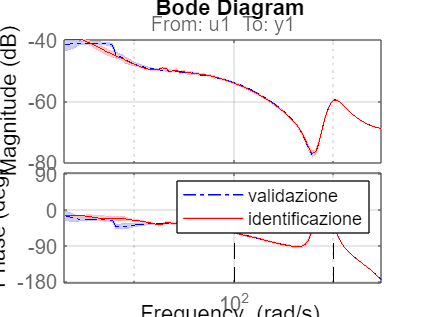

figure
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
h=bodeplot(frequency_response_validazione_g2,'b-.', bode_opts);
showConfidence(h,3)
hold on
bode(frequency_response_identification_g2, bode_opts,'r')
plot([weight1_1 weight1_1],ylim,'--k')
plot([weight1_2 weight1_2],ylim,'--k')
grid on

legend('validazione','identificazione')
xlim([2 3e3])

# Tutti e due al terzo ordine

### Giunto 1

peso = ones(length(frequency_response_identification_g1.Frequency),1);

weight1_1 = 100;
weight1_2 = 1000;

peso(frequency_response_identification_g1.Frequency<weight1_1) = 1e-3;
peso(frequency_response_identification_g1.Frequency>weight1_2) = 1e-3;   

Stima dei modelli continuo e discreto del primo giunto.

opts = ssestOptions('WeightingFilter', peso, 'EnforceStability', 1);
modello_continuo_g13 = ssest(frequency_response_identification_g1, 3, opts);
modello_discreto_g13 = ssest(frequency_response_identification_g1, 3, 'Ts', st, opts);  %ordine

Confronto con la risposta in frequenza del primo giunto.

figure
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on'; %Evitare la molteplicità di 2pi nella fase

h = bodeplot(frequency_response_identification_g1, bode_opts);
hold on
showConfidence(h,3)
bode(modello_continuo_g13,modello_discreto_g13, bode_opts)

%Inserimento linee per frequenze che limitano gli intervalli pesati
plot([weight1_1 weight1_1],ylim,'--k')
plot([weight1_2 weight1_2],ylim,'--k')

grid on
xlim([10 2e3]) %limite range di freq plottato

legend('Identification 1','Modello continuo 1','Modello discreto 1')

### Giunto 2

peso = ones(length(frequency_response_identification_g2.Frequency),1);

weight2_1 = 250;
weight2_2 = 1000;

peso(frequency_response_identification_g2.Frequency<weight2_1) = 1e-3;
peso(frequency_response_identification_g2.Frequency>weight2_2) = 1e-3;   

Stima dei modelli continuo e discreto del secondo giunto.

opts=ssestOptions('WeightingFilter',peso,'EnforceStability',1);
modello_continuo_g23 = ssest(frequency_response_identification_g2,3,opts);
modello_discreto_g23 = ssest(frequency_response_identification_g2,3,'Ts',st,opts);

Confronto con la risposta in frequenza del secondo giunto

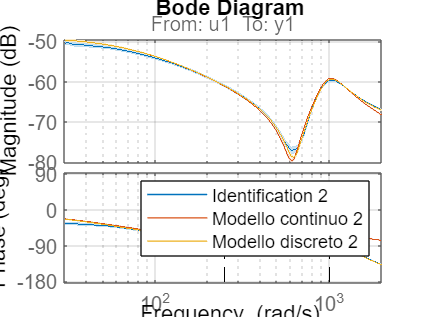

figure
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on'; %Evitare la molteplicità di 2pi nella fase

h=bodeplot(frequency_response_identification_g2, bode_opts);
hold on
showConfidence(h,3)
bode(modello_continuo_g23,modello_discreto_g23, bode_opts)

%Inserimento linee per frequenze che limitano gli intervalli pesati
plot([weight2_1 weight2_1],ylim,'--k')
plot([weight2_2 weight2_2],ylim,'--k')


hold off
grid on
xlim([30 2e3]) %limite range di freq plottato

legend('Identification 2','Modello continuo 2','Modello discreto 2')

# Tutti e due al quinto ordine

Stima dei modelli del terzo ordine a partire dai risultati ottenuti sui due giunti.

### Giunto 1

peso = ones(length(frequency_response_identification_g1.Frequency),1);

weight1_1 = 100;
weight1_2 = 1000;

peso(frequency_response_identification_g1.Frequency<weight1_1) = 1e-3;
peso(frequency_response_identification_g1.Frequency>weight1_2) = 1e-3;   

Stima dei modelli continuo e discreto del primo giunto.

opts = ssestOptions('WeightingFilter', peso, 'EnforceStability', 1);
modello_continuo_g15 = ssest(frequency_response_identification_g1, 5, opts);
modello_discreto_g15 = ssest(frequency_response_identification_g1, 5, 'Ts', st, opts);  %ordine

Confronto con la risposta in frequenza del primo giunto.

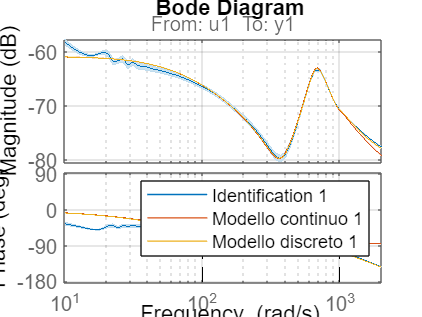

figure
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on'; %Evitare la molteplicità di 2pi nella fase

h = bodeplot(frequency_response_identification_g1, bode_opts);
hold on
showConfidence(h,3)
bode(modello_continuo_g15,modello_discreto_g15, bode_opts)

%Inserimento linee per frequenze che limitano gli intervalli pesati
plot([weight1_1 weight1_1],ylim,'--k')
plot([weight1_2 weight1_2],ylim,'--k')

grid on
xlim([10 2e3]) %limite range di freq plottato

legend('Identification 1','Modello continuo 1','Modello discreto 1')

### Giunto 2

peso = ones(length(frequency_response_identification_g2.Frequency),1);

weight2_1 = 250;
weight2_2 = 1000;

peso(frequency_response_identification_g2.Frequency<weight2_1) = 1e-3;
peso(frequency_response_identification_g2.Frequency>weight2_2) = 1e-3;   

Stima dei modelli continuo e discreto del secondo giunto.

opts=ssestOptions('WeightingFilter',peso,'EnforceStability',1);
modello_continuo_g25 = ssest(frequency_response_identification_g2,5,opts);
modello_discreto_g25 = ssest(frequency_response_identification_g2,5,'Ts',st,opts); 

Confronto con la risposta in frequenza del secondo giunto

figure
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on'; %Evitare la molteplicità di 2pi nella fase

h=bodeplot(frequency_response_identification_g2, bode_opts);
hold on
showConfidence(h,3)
bode(modello_continuo_g25,modello_discreto_g25, bode_opts)

%Inserimento linee per frequenze che limitano gli intervalli pesati
plot([weight2_1 weight2_1],ylim,'--k')
plot([weight2_2 weight2_2],ylim,'--k')


hold off
grid on
xlim([30 2e3]) %limite range di freq plottato

legend('Identification 2','Modello continuo 2','Modello discreto 2')

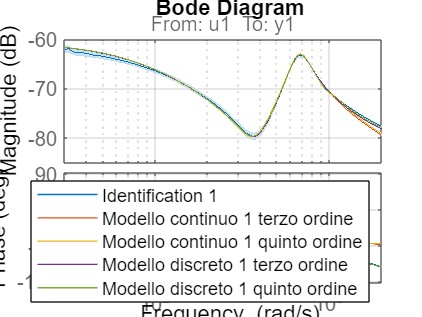

figure
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on'; %Evitare la molteplicità di 2pi nella fase
h=bodeplot(frequency_response_identification_g1, bode_opts);

hold on
showConfidence(h,3)
bode(modello_continuo_g13,modello_continuo_g15,modello_discreto_g13,modello_discreto_g15, bode_opts)

%Inserimento linee per frequenze che limitano gli intervalli pesati
plot([weight2_1 weight2_1],ylim,'--k')
plot([weight2_2 weight2_2],ylim,'--k')


hold off
grid on
xlim([30 2e3]) %limite range di freq plottato

legend('Identification 1','Modello continuo 1 terzo ordine','Modello continuo 1 quinto ordine','Modello discreto 1 terzo ordine','Modello discreto 1 quinto ordine')

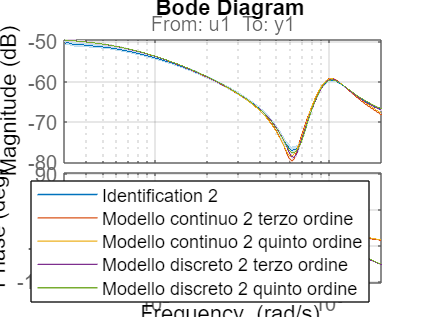

figure
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on'; %Evitare la molteplicità di 2pi nella fase
h=bodeplot(frequency_response_identification_g2, bode_opts);

hold on
showConfidence(h,3)
bode(modello_continuo_g23,modello_continuo_g25,modello_discreto_g23,modello_discreto_g25, bode_opts)

%Inserimento linee per frequenze che limitano gli intervalli pesati
plot([weight2_1 weight2_1],ylim,'--k')
plot([weight2_2 weight2_2],ylim,'--k')


hold off
grid on
xlim([30 2e3]) %limite range di freq plottato

legend('Identification 2','Modello continuo 2 terzo ordine','Modello continuo 2 quinto ordine','Modello discreto 2 terzo ordine','Modello discreto 2 quinto ordine')